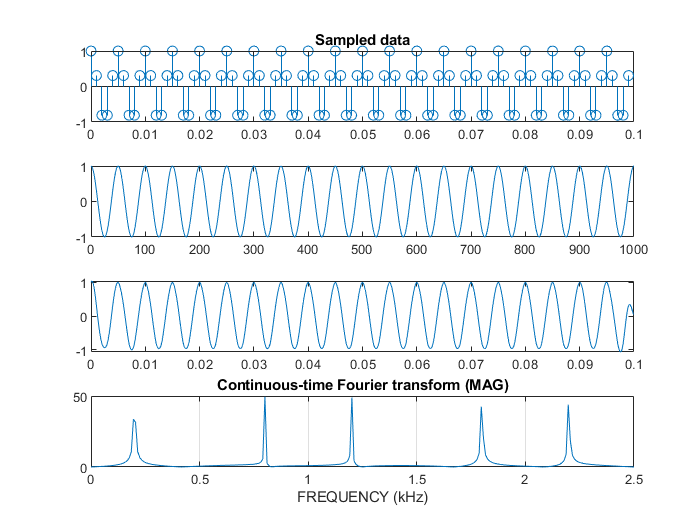

clear all;
close all;
clc;

N = 100;
fs = 1000;
fs_cheating = 10000;
n = 0:N-1;
T_cheating = 1 / fs_cheating;
T = 1 / fs;
f = 200;
y = cos(2*pi*f*n*T);
subplot(4,1,1);
y = stem(n*T, y);
samples_data = y.YData;
title('Sampled data');
subplot(4,1,2);
n_cheating = 0:0.1 * fs_cheating;
y_cheating = cos(2*pi*f*n_cheating*T_cheating);
plot(n_cheating, y_cheating);

t_for_sinc = -10*T : T_cheating : 10*T;
Ht = sinc(t_for_sinc / T);
% plot(t_for_sinc, Ht);
spike_train = zeros(1000,1)';
index = 1;
for i = 1:1000
    if mod(i,10)==1
        spike_train(i) = samples_data(index);
        index = index + 1;
    end
end

signal_recovered = conv(spike_train, Ht, 'same'); % Same size as spike_train
t_for_plot = 0 : T_cheating : 0.1-T_cheating;
subplot(4,1,3)
plot(t_for_plot, signal_recovered);

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
subplot(4,1,4);
fmagplot(spike_train, 1e-4);

hold off;

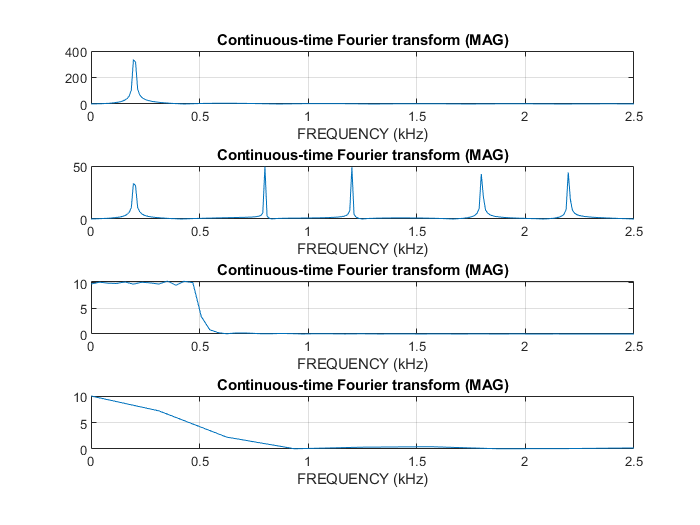

figure

subplot(4,1,1);
fmagplot(y_cheating,1e-4);
subplot(4,1,2);
fmagplot(spike_train, 1e-4);
subplot(4,1,3);
fmagplot(Ht, 1e-4);
subplot(4,1,4);
x = -1e-3:1e-4:1e-3;
linear_result = (1e-3 - abs(x)) / 1e-3;
fmagplot(linear_result, 1e-4);

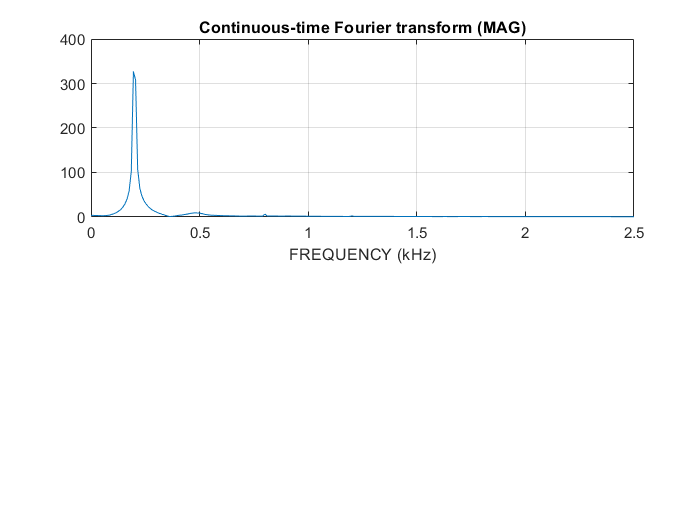


figure
% Frequency plot for recovered signal based on sinc.
subplot(2,1,1);
fmagplot(signal_recovered, 1e-4);